clear all
clf

format longg
Re = 1000;
mu = 0.0010014; %dynamisk viscusitet
rho = 997; %kg/m^3
d = 0.060; %m

U = Re * mu / (rho * d)

U =          0.016740220661986




v_min = 0.00157275

v_min =                 0.00157275


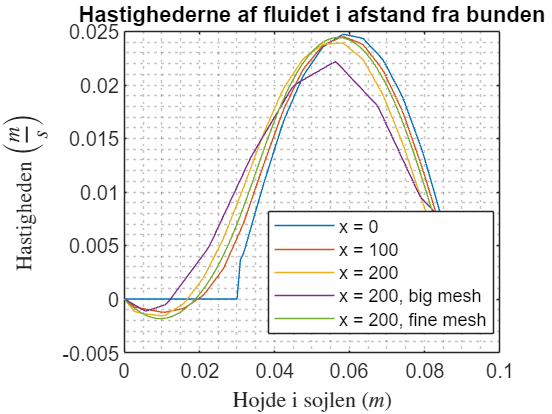


format longg
% Define the filename and sheetname
sheetname = 'Plot Data';

% Import data from Excel file
[numericData1, textData, rawData] = xlsread("Orego.xlsx", sheetname);
Y = numericData1(:,1);
U_Orego = numericData1(:,2);

[numericData2, textData, rawData] = xlsread("Orego+100.xlsx", sheetname);
U_Orego100 = numericData2(:,2);

[numericData3, textData, rawData] = xlsread("Orego+200.xlsx", sheetname);
U_Orego200 = numericData3(:,2);

[numericData4, textData, rawData] = xlsread("2Orego+200.xlsx", sheetname);
U_2Orego200 = numericData4(:,2);

[numericData5, textData, rawData] = xlsread("3Orego+200.xlsx", sheetname);
U_3Orego200 = numericData5(:,2);

plot(Y, U_Orego, DisplayName='x = 0');
hold on
plot(Y, U_Orego100, DisplayName='x = 100');
plot(Y, U_Orego200, DisplayName='x = 200');
plot(Y, U_2Orego200, DisplayName='x = 200, big mesh');
plot(Y, U_3Orego200, DisplayName='x = 200, fine mesh');
title('Hastighederne af fluidet i afstand fra bunden');
xlabel('Hojde i sojlen $(m)$',Interpreter='latex')
ylabel('Hastigheden $\left(\frac{m}{s}\right)$', Interpreter='latex')
grid("minor")
legend('Location', 'best')
hold off


procentvis_afvigelse = mean(abs(U_Orego200(2:end) - U_2Orego200(2:end))./abs(U_Orego200(2:end))) * 100

procentvis_afvigelse =           57.5738916059018



procentvis_afvigelse3 = mean(abs(U_Orego200(2:end) - U_3Orego200(2:end))./abs(U_Orego200(2:end))) * 100

procentvis_afvigelse3 =           25.7110473452308



procentvis_afvigelse3 = mean(abs(U_3Orego200(2:end) - U_Orego200(2:end))./abs(U_3Orego200(2:end))) * 100

procentvis_afvigelse3 =           36.7526415158018
